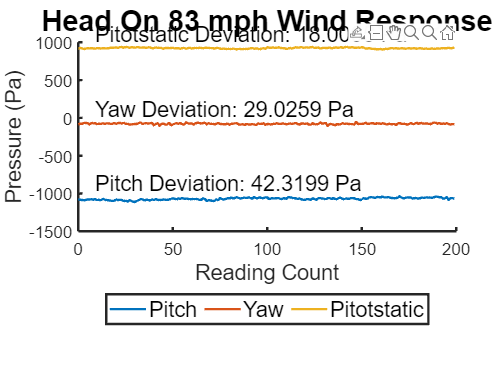

% Specify the file name
filename = '.\data_files\MVP2\Pitch_fast\0deg.csv';

% Read the data from the CSV file
data = readmatrix(filename);

% Extract columns
Reading_Count = data(:, 1);
Pitch = data(:, 2);
Yaw = data(:, 3);
Pitotstatic = data(:, 4);

% Calculate and display jitter for Pitch
jitter_Pitch = max(Pitch) - min(Pitch);
mean_Pitch = mean(Pitch);
pitch_skew = max(max(Pitch) - mean_Pitch, mean_Pitch - min(Pitch));

% Calculate and display jitter for Yaw
jitter_Yaw = max(Yaw) - min(Yaw);
mean_Yaw = mean(Yaw);
yaw_skew = max(max(Yaw) - mean_Yaw, mean_Yaw - min(Yaw));

% Calculate and display jitter for Pitotstatic
jitter_Pitotstatic = max(Pitotstatic) - min(Pitotstatic);
mean_Pitotstatic = mean(Pitotstatic);
pitotstatic_skew = max(max(Pitotstatic) - mean_Pitotstatic, mean_Pitotstatic - min(Pitotstatic));

% Plot the data
figure;
hold on;

% Plot Pitch
plot(Reading_Count, Pitch, 'DisplayName', 'Pitch', 'LineWidth', 2.0);

% Plot Yaw
plot(Reading_Count, Yaw, 'DisplayName', 'Yaw', 'LineWidth', 2.0);

% Plot Pitotstatic
plot(Reading_Count, Pitotstatic, 'DisplayName', 'Pitotstatic', 'LineWidth', 2.0);

% Add text for skew for each line
text(Reading_Count(10), max(Pitch), sprintf('Pitch Deviation: %.4f Pa', pitch_skew), 'VerticalAlignment', 'bottom', 'FontSize', 18);
text(Reading_Count(10), max(Yaw), sprintf('Yaw Deviation: %.4f Pa', yaw_skew), 'VerticalAlignment', 'bottom', 'FontSize', 18);
text(Reading_Count(10), max(Pitotstatic), sprintf('Pitotstatic Deviation: %.4f Pa', pitotstatic_skew), 'VerticalAlignment', 'bottom', 'FontSize', 18);

% Add legend below the graph
legend('Location', 'southoutside', 'Orientation', 'horizontal', 'FontSize', 18);

% Adjust the figure layout
set(gca, 'FontSize', 14, 'LineWidth', 2.0);
xlabel('Reading Count', 'FontSize', 18);
ylabel('Pressure (Pa)', 'FontSize', 18);
title('Head On 83 mph Wind Response', 'FontSize', 24);